# ECSE 343 Final Exam Question 2 (10 Marks)

Posted at 9:00AM April 19, 2021

Due at 9:00AM April 22, 2021

**This final has three Questions. Each question is submitted as a seperate 'assignment'.** 

## ** Question 2**

Question two is very similar to question 1 but with different set of data. In this case as well, you know that Ydata contains zero-mean gaussian noise. 

You may run the following code in order to display the data (make sure Q2data.mat is in your working directory):

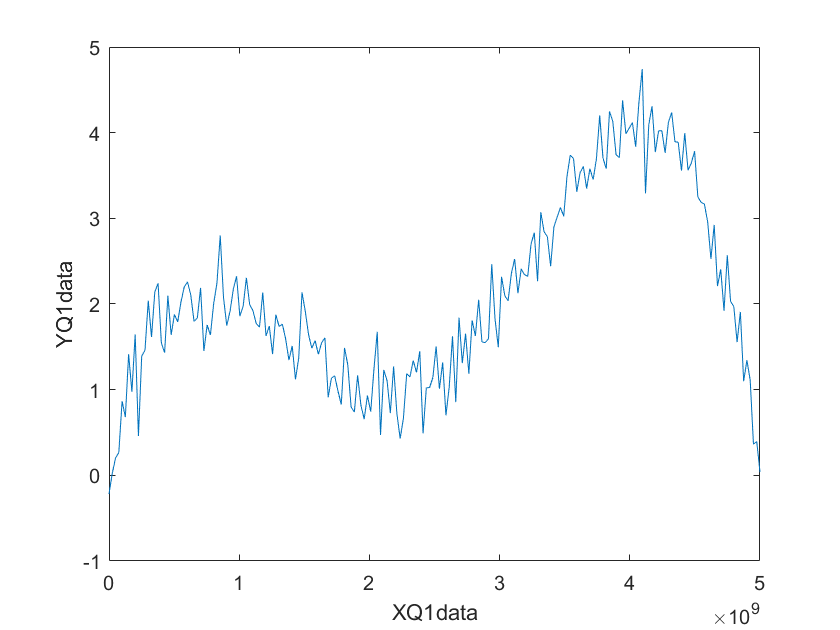

clear all
clf
load Q2data

plot(Xdata,Ydata)
xlabel('XQ1data')
ylabel('YQ1data')

**Part 1 (5 Marks)**

Use the techniques we studied in this course in order to find a plot a better estimate of Ydata and store it in Yest. You may use (if needed) the following matlab builtin functions: qr, lu, chol, svd, eig, polyval, and the '\' operator as in x = A\b. Feel free to copy and include any code you used in Question 1 that you deem useful for this question. Include and run your code below

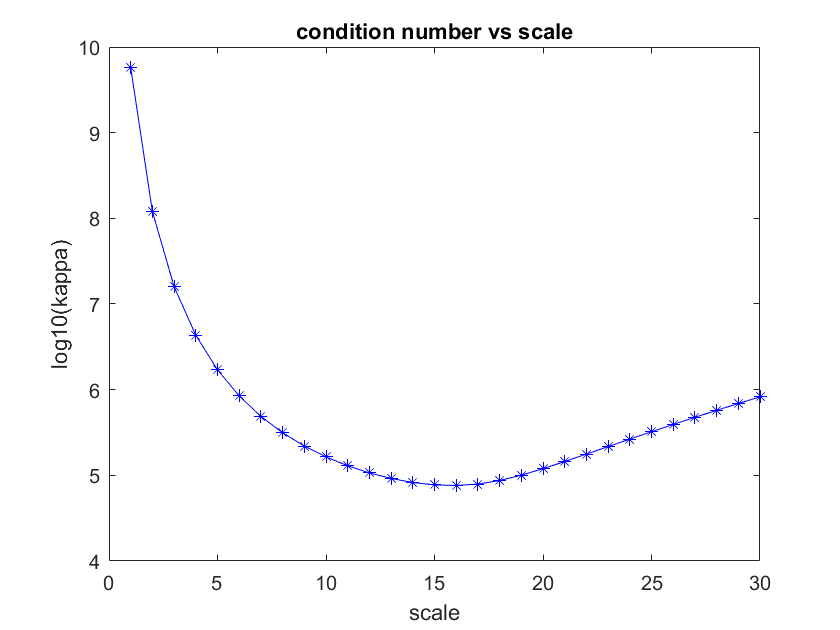

% Load and plot original data
clear all
clf
load Q2data  %make sure Q2data.mat is in your current directory

%%% Your code to compute Yest should go below
%%% testing scale
scale_max = 30;
deg = 7;
for i = 1:scale_max
    As = Least_squared_scaled(deg,0.1*i*mean(Xdata),Xdata);
    cond_num(i)=cond(As);
end
figure(1)
plot(1:scale_max,log10(cond_num),'b-*')
ylabel('log10(kappa)');
xlabel('scale');
title('condition number vs scale')

%%% Q2 solution
Xdata = Xdata/(1.6*mean(Xdata));%scaling
powers=0:deg;
Yest = zeros(size(Ydata));
A = PolynomialMatrix(Xdata,deg)

A =     1.0000         0         0         0         0         0         0         0
    1.0000    0.0063    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.0126    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.0188    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.0251    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.0314    0.0010    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.0377    0.0014    0.0001    0.0000    0.0000    0.0000    0.0000
    1.0000    0.0440    0.0019    0.0001    0.0000    0.0000    0.0000    0.0000
    1.0000    0.0503    0.0025    0.0001    0.0000    0.0000    0.0000    0.0000
    1.0000    0.0565    0.0032    0.0002    0.0000    0.0000    0.0000    0.0000


cond(A)

ans = 7.6123e+04


% Compute the coefficients 
[Q,R] = qr(A);
Ar = R\(Q'*Ydata')

Ar =    -0.0387
   30.1444
 -149.8637
  350.4871
 -537.5887
  577.9132
 -350.2001
   83.2378



for I = 1:length(powers)
    Yest = Yest + Ar(I)*Xdata.^powers(I);
end

residual = norm((Yest-Ydata),2)

residual = 4.0356

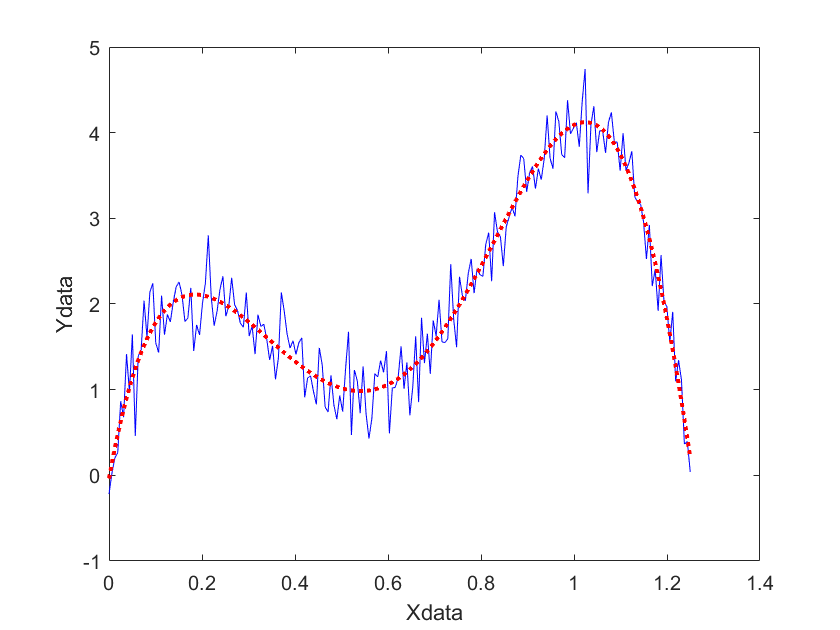

% Plot the results of your estimate and compare to original data
% The code below assumes you have already computed Yest 
plot(Xdata,Ydata,'b')
xlabel('Xdata')
ylabel('Ydata')
hold on
plot(Xdata,Yest,'r:','LineWidth',2)

function M = PolynomialMatrix(x,n)
% write your code here
 % n is the degree of the polynomila
 % x is the vector of input data
 powers=0:n; 
     for I = 1:length(powers)
         M(:,I)=x.^powers(I);
     end
end

function M = Least_squared_scaled(deg,scale,x)
% write your code here
 % n is the degree of the polynomila
 % x is the vector of input data
 powers=0:deg; 
 x_new = x./scale;
     for I = 1:length(powers)
         M(:,I)=x_new.^powers(I);
     end
end

**Part 2 (5 Marks)**

What accuracy improvement method was more important in Question 2 than it was in Question 1? (note that some of you may have already incorporated this in their answer for question 1 even if it was less critical there). Explain why it is important.You may type your answer below. or include it in an attached pdf file. If you choose the latter, please put a note below indicating that the answer is in the attached pdf file.

The accuracy improvement before and after sacling is more important in Question 2, since the number in the Xdata in very large which makes the polynomial matrix ill-conditioned. In Question 1, we do not observe very large change in the fitting before we implement scaling, but in Question 2, we do not get a correct fitting behavior unless we scale Xdata. This is because of the signicant large numbers in Xdata. By calculating the mean of Xdata, we get 2.5e+9 while the mean of Xdata is only 2.5. SInce the condition number is huge, we would be using a similar approach to Q1 to find the optimized scale for our chosen degree of 7. Since the numbers are large, we first need to set up a unit to accomadate them. We choose to use the mean value of Xdata as our unit and multiply it with certain coefficients. We define the coefficients' range that we want to search to be from 1 to 30 and our step size is 1. After running our plot, we can see that the condition number is the lowest at coefficient=1.6. So I divide Xdata by 1.6*mean(Xdata) to scale it. By scaling, the condition number of the polynomial matrix we need to calculate is reduced from infinite to 7.6123e+4, which is a much more significant improvement compared to Q1. Also, to evaluate whether I have a better fitting, I also calculated the residual before and after scaling. The result shows the residual is decreased from 15.6482 to 4.0356, which is another proof that my scaling effectively increases the accuracy other than just observing the fitting behavior. In summary, it is very important to scale before we calculate polynomial coefficients using QR because large condition number will cause numerical errors when calculating A.